clear all;
close all;
clc;

    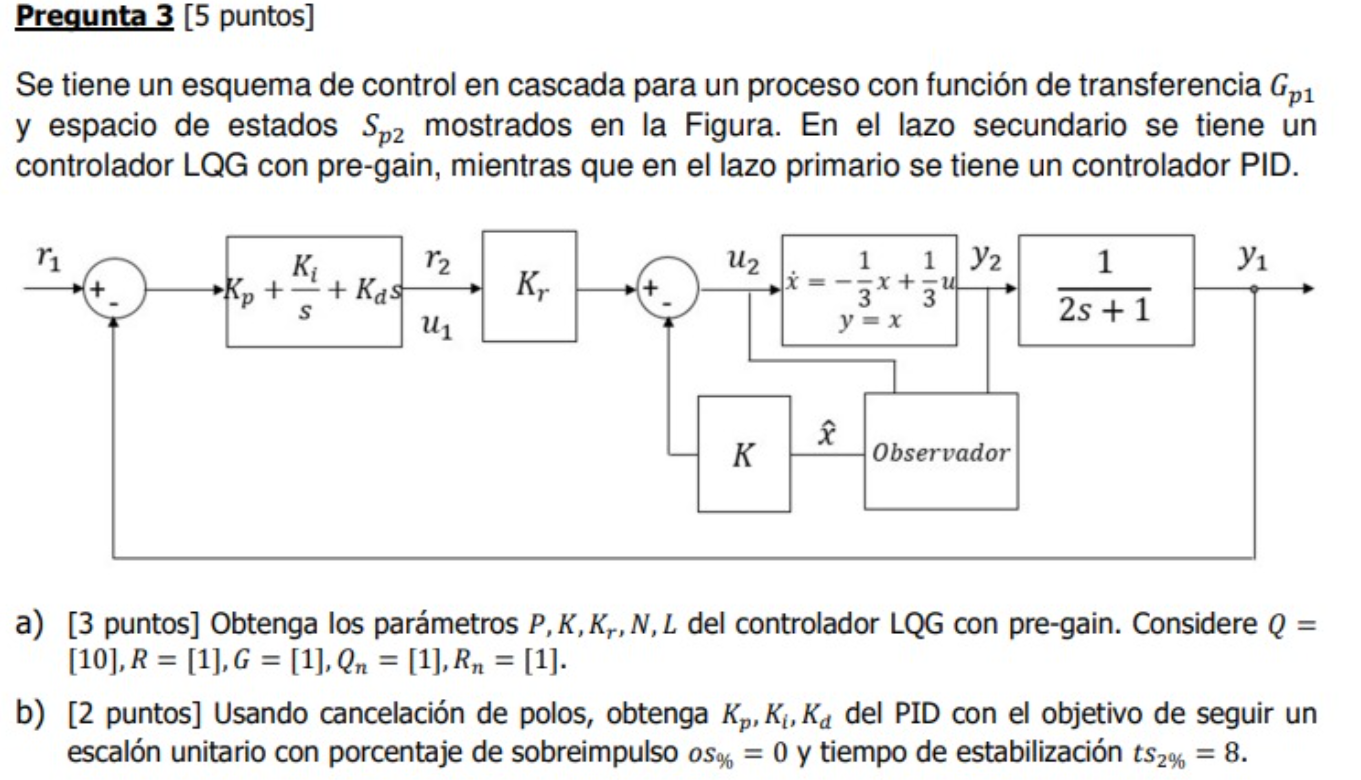

%% LAZO INTERNO:
%Espacio estados
s=tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


A=-1/3

A = -0.3333

B=1/3

B = 0.3333

C=1

C = 1

D=0

D = 0

Q=[10] % Matriz Q(Preferencia Estados)

Q = 10

R=[1] % Matriz R(Esfuerzo de controll)

R = 1

G=[1] 

G = 1

Qn=[1] % Ruido

Qn = 1

Rn=[1]

Rn = 1

[K,P]=lqr(A,B,Q,R) % Calculamos el K y P para la parte de LQR

K = 2.3166

P = 6.9499

Kr=inv(D-(C-D*K)*inv(A-B*K)*B) % Calculamos el Kr para el pregain

Kr = 3.3166

[L, N] = lqe(A, G, C, Qn, Rn) % Calculamos el L y n para la parte de LQG

L = 0.7208

N = 0.7208

**LQG CON PREGAIN(LAZO CERRADO):**

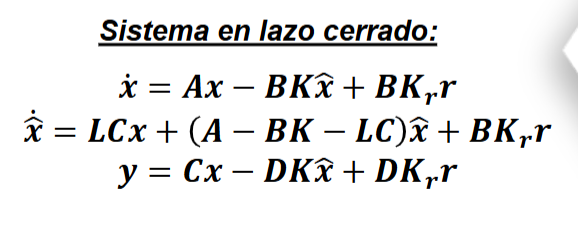

At2=[A -B*K;
    L*C (A-B*K-L*C)]

At2 =    -0.3333   -0.7722
    0.7208   -1.8263


Bt2=[B*Kr; B*Kr]

Bt2 =     1.1055
    1.1055


Ct2=[1 0]

Ct2 =      1     0


Dt2=0

Dt2 = 0

st2=ss(At2,Bt2,Ct2,Dt2)


st2 =
 
  A = 
            x1       x2
   x1  -0.3333  -0.7722
   x2   0.7208   -1.826
 
  B = 
          u1
   x1  1.106
   x2  1.106
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Gt2=tf(st2)


Gt2 =
 
    1.106 s + 1.165
  --------------------
  s^2 + 2.16 s + 1.165
 
Continuous-time transfer function.
Model Properties


%% LAZO EXTERNO:
G1=1/(2*s+1);


G1 =
 
     1
  -------
  2 s + 1
 
Continuous-time transfer function.
Model Properties


Gs1=1;
Gl1=1/(2*s) %% Gl1=Gc1*Gt2*Gp1*Gs1 --> Gc1= Gl1/(Gt2*Gp1*Gs1) 


Gl1 =
 
   1
  ---
  2 s
 
Continuous-time transfer function.
Model Properties


Gc1=minreal((Gl1)/(Gt2*G1),1e-6)


Gc1 =
 
  0.9045 s^2 + 1.452 s + 0.5
  --------------------------
              s
 
Continuous-time transfer function.
Model Properties
